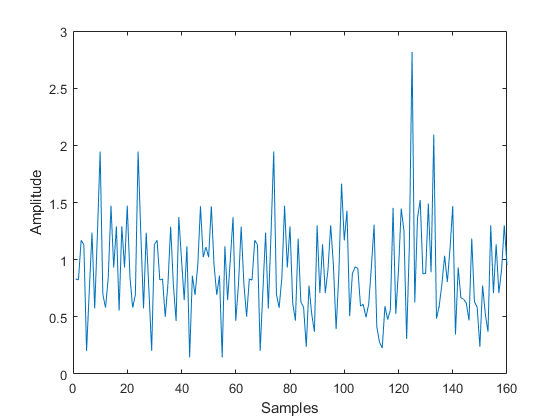

%% Generate VHTSIGA by wlanVHTSIGA(cfgVHT)
cfgVHT = wlanVHTConfig;
cfgVHT.ChannelBandwidth = 'CBW20';
cfgVHT.MCS= 8;
[y,bits] = wlanVHTSIGA(cfgVHT);
plot(abs(y))
xlabel('Samples')
ylabel('Amplitude')


bit34 = bits(1:34);
window = ones(8,1);
for n=1:length(bit34)
    a = xor(window(1),bit34(n));
    window(1:5) = window(2:6);
    window(6) = xor(window(7),a);
    window(7) = xor(window(end),a);
    window(end) = a;   
end
crc = ~window;

## Encoding

% BCC Encoder
bcc_encodedData   = wlanBCCEncode(bits,'1/2');
size(bcc_encodedData)

ans =     96     1


% BCC Interleaver
number_CBPSSI = 48; % number of coded bits per OFDM symbol per spatial stream per interleaver block
cbw = 'CBW20';
out = wlanBCCInterleave(bcc_encodedData,'Non-HT',number_CBPSSI,cbw);

size(out)

ans =     96     1



out_(:,1)=out(1:48);
out_(:,2)=out(49:96);

% Interleaver self-made
Nbpscs = 1 ;
Ncbps = 48;
kkk = (0:Ncbps-1)';
% kkk_ = (0:Ncbps-1)';
% iii = zeros(Ncbps,1);
% jjj = zeros(Ncbps,1);
s = max(1,Nbpscs/2);
permutation_first = zeros(Ncbps,1);
permutation_second = zeros(Ncbps,1);

% for ppp=1:length(kkk)
%     iii(ppp) = Ncbps/16 *mod(kkk(ppp),16)+floor(kkk(ppp)/16);
% end

% for ppp=1:length(kkk)
%     jjj(ppp) = s*floor(kkk_(ppp)/s)+mod((kkk_(ppp)+Ncbps-floor(kkk_(ppp)*16/Ncbps)),s);
% end

first48 = bcc_encodedData(1:48);

%% first index permutation
iii = Ncbps/16 *mod(kkk,16)+floor(kkk/16);


for cc = 1:length(kkk)
    permutation_first(iii(cc)+1) = first48(cc);
end
%% second index  permutation
jjj = s*floor(kkk/s)+mod((kkk+Ncbps-floor(kkk*16/Ncbps)),s);

for cc = 1:length(kkk)
    permutation_second(jjj(cc)+1) = permutation_first(cc);
end

% Constellation Mapper 
numBPSCS = 1; % Number of coded bits per subcarrier per spatial stream
phase = [0 pi/2]; % BPSK and QBPSK
mappedData = wlanConstellationMap(out_,numBPSCS,phase);

% scatterplot(mappedData(:,1))
% scatterplot(mappedData(:,2))

% Pilot Insertion
out_insert1=[mappedData(1:5,1);1;mappedData(6:18,1);1;mappedData(19:30,1);1;mappedData(31:43,1);-1;mappedData(44:48,1)];
out_insert2=[mappedData(1:5,2);1;mappedData(6:18,2);1;mappedData(19:30,2);1;mappedData(31:43,2);-1;mappedData(44:48,2)];


% The unpopulated bits are 0
out_full1 = [zeros(6,1);out_insert1(1:26);0;out_insert1(27:52);zeros(5,1)];
out_full2 = [zeros(6,1);out_insert2(1:26);0;out_insert2(27:52);zeros(5,1)];

% k = -26:1:26;
% k =  k' 
% k(27) = [];

% TGI = 800 * 10^(-8);
% detF = 312.5*1000;

k = -32:1:31;
k =  k' ;
% k(27) = [];
ifft1 = zeros(64,1);
ifft2 = zeros(64,1);

% IFFT 
for nn = 1:64       
        yy = out_full1 .* exp(j*2*pi*k*(nn-1)/64);
        ifft1(nn) = (1/sqrt(52)) * sum(yy) ;
        yy = out_full2 .* exp(j*2*pi*k*(nn-1)/64);
        ifft2(nn) = (1/sqrt(52)) * sum(yy) ;
end
% ifft1 =(1/sqrt(52))* ifft(out_full1)*64;
% ifft2 =(1/sqrt(52))* ifft(out_full2)*64;

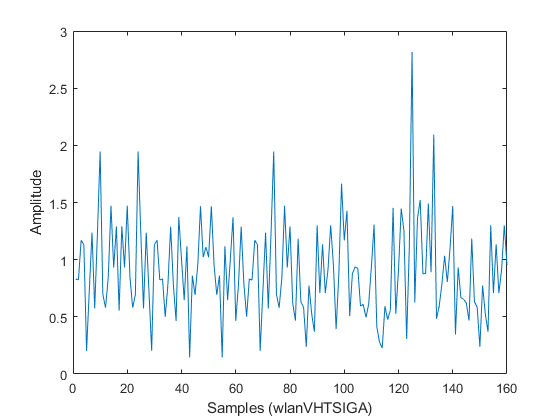

% Add CP
out_cp = [ifft1(49:64);ifft1(1:64);ifft2(49:64);ifft2(1:64)];

% 
% out_ifft1 = ifft(out_full1);
% out_ifft2 = ifft(out_full2);

% out_ifft = [out_ifft1;out_ifft2];

xx1 = abs(y);
xx2 = abs(out_cp);

plot(abs(y))
xlabel('Samples (wlanVHTSIGA)')
ylabel('Amplitude')

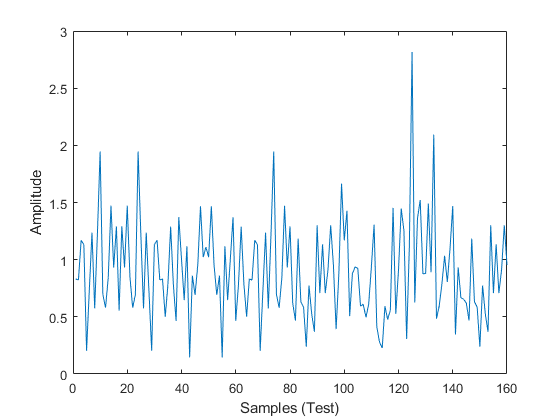


% hold on
plot(abs(out_cp))
xlabel('Samples (Test)')
ylabel('Amplitude')

## Decoding

% FFT
recx = zeros(64,2);
recx(:,1) = out_cp(17:80);
recx(:,2) = out_cp(97:160);

k2 = 1:1:64;
k2 = k2';
STFfft = zeros(64,2);

for kk = 1:64       
        yy =  sqrt(52) *recx(:,1) .* exp(-j*2*pi*(kk-33)*(k2-1)/64);
        STFfft(kk,1) = 1/64 *  sum(yy) ;
end

for kk = 1:64       
        yy =  sqrt(52) *recx(:,2) .* exp(-j*2*pi*(kk-33)*(k2-1)/64);
        STFfft(kk,2) = 1/64 *  sum(yy) ;
end
% full = [STFfft(:,1);STFfft(:,2)];

% Extract 48 data bits
BF_mod = zeros(48,2);
BF_mod(:,1) = [STFfft(7:11,1);STFfft(13:25,1);STFfft(27:32,1);STFfft(34:39,1);STFfft(41:53,1);STFfft(55:59,1)];
BF_mod(:,2) = [STFfft(7:11,2);STFfft(13:25,2);STFfft(27:32,2);STFfft(34:39,2);STFfft(41:53,2);STFfft(55:59,2)];

% Constellation Demapper 
% numBPSCS = 1; % Number of coded bits per subcarrier per spatial stream
% phase = [0 pi/2]; % BPSK and QBPSK
% noiseVar = 0;
demappedData = wlanConstellationDemap(BF_mod,0,numBPSCS,phase);
demappedBits = (demappedData<=0);
isequal(out_,demappedBits)

ans = logical
   1


% BCC Deinterleaver

number_CBPSSI = 48; % number of coded bits per OFDM symbol per spatial stream per interleaver block
cbw = 'CBW20';
full_demap = [demappedBits(:,1);demappedBits(:,2)];
full_demap = double(full_demap);

% isequal(out,full_demap)

deinterleave = wlanBCCDeinterleave(full_demap,'Non-HT',number_CBPSSI,cbw);
size(deinterleave)

ans =     96     1


isequal(bcc_encodedData,deinterleave)

ans = logical
   1


% BCC Decoder

% 
% bcc_deCodedData = wlanBCCDecode(deinterleave,'1/2','hard',tDepth);
% size(bcc_deCodedData)
% isequal(bcc_deCodedData,bits)